# Graphing in MATLAB

In this live script I play with the graph functions of MATLAB to plot dense networks. I start off with the connectivity matrix of the average over 14 healthy brains J. Using the 'subspace' layout option for the graphs, the graphs are plotted according to some kind of method which draws graphs from eigenvectors. The result seems to be that the whole brain connectivity organizes itself into clusters resembling the physical brain. Furthermore, applying this method to the transition probabilty matrix of the Ising model (for the DMN network and N = 5) gives an interesting structure as well whose symmetries are quite obvious observationally. 

These methods might prove to be useful to understanding different kinds of connectivities and transition matrices visually. 

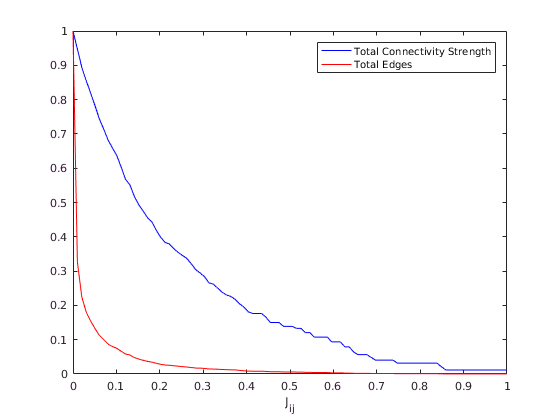

% load connectivity matrix
wd = '/home/heysoos/Dropbox/Masters Thesis/Codes/Phi';
cd(wd);

J = load('MJ_all.mat');
J = J.MJ_all_mn;
J = J./(max(max(J)));

Jw = J;

loop = linspace(min(min(Jw)),max(max(Jw)),100);

for i = 1:100
    Jw(Jw < loop(i)) = 0;
    Jwedge(i) = sum(find(Jw));
    JwSum(i) = sum(sum(Jw));
end
plot(loop,JwSum./(max(JwSum)),'b',loop,Jwedge./(max(Jwedge)),'r')
legend('Total Connectivity Strength','Total Edges')
xlabel('J_{ij}')
ylim([0 1])

Zoom in a little on the region in [0, 0.1]

Jw = J;

loop = linspace(min(min(Jw)),max(max(Jw))/20,100);

for i = 1:100
    Jw(Jw < loop(i)) = 0;
    Jwedge(i) = sum(find(Jw));
    JwSum(i) = sum(sum(Jw));
end
plot(loop,JwSum./(max(JwSum)),'b',loop,Jwedge./(max(Jwedge)),'r')
legend('Total Connectivity Strength','Total Edges')
xlabel('J_{ij}')
ylim([0 1])

Can use this information to decide how to threshold J. For reference, here's what the connectivity matrix looks raw:

G = graph(J);

G =   graph with properties:

    Edges: [3290×2 table]
    Nodes: [83×0 table]


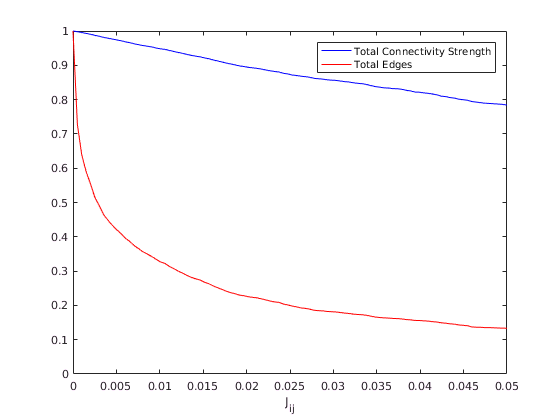

deg = degree(G);

edgeC = [0.7, 0.7, 0.7];

LWidths = G.Edges.Weight/max(G.Edges.Weight);
LWidths = log(LWidths)-min(log(LWidths)) + eps; % normalized

colormap cool                                       % set color map

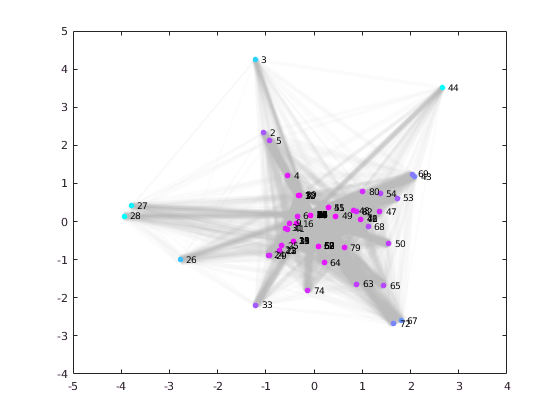

H = plot(G, 'Layout', 'subspace', 'MarkerSize',log(deg), ...               % node size in log scale
    'NodeCData',deg,...                             % node color by degree
    'EdgeColor',edgeC,'EdgeAlpha',0.05,'LineWidth',LWidths);

We can get rid of 50% of the edges by thresholding near 0.005 * max(J) while maintaining 

Jthresh = J;
Jthresh(J < 0.012*max(max(J))) = 0;
G = graph(Jthresh);

G =   graph with properties:

    Edges: [940×2 table]
    Nodes: [83×0 table]


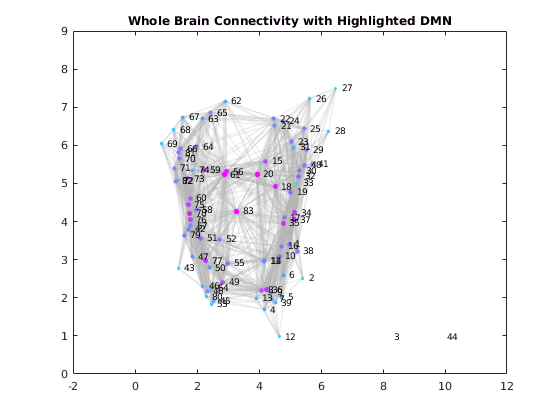

deg = degree(G);

edgeC = [0.7, 0.7, 0.7];

LWidths = G.Edges.Weight/max(G.Edges.Weight);
LWidths = log(LWidths)-min(log(LWidths)) + eps; % normalized

colormap cool                                       % set color map
H1 = plot(G, 'Layout', 'subspace', 'MarkerSize',log(deg+1+eps), ...               % node size in log scale
    'NodeCData',deg,...                             % node color by degree
    'EdgeColor',edgeC,'EdgeAlpha',0.3,'LineWidth',LWidths);
title('Whole Brain Connectivity with Highlighted DMN')

Let's try highlighting the DMN network:

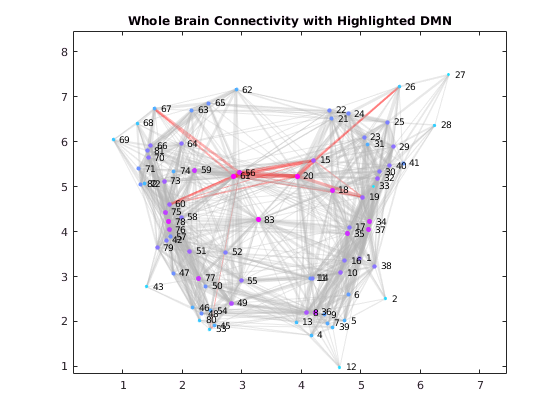

load('/home/heysoos/Dropbox/Masters Thesis/Codes/Phi/zmaps/Pubu/template_data.mat')
mean_RSN_orig = mean_RSN;

mean_RSN = mean_RSN_orig(:,2); % DMN zmap
[~, I] = sort(mean_RSN);
DMNnodes = I(end-10:end);

for i = 1:length(DMNnodes)
    DMNedges = intersect(neighbors(G,DMNnodes(i)),DMNnodes(DMNnodes~=DMNnodes(i)));
    highlight(H1, DMNnodes(i),DMNedges,'EdgeColor','red')
end

xlim([0.17 7.46])
ylim([0.83 8.47])


% H1 = plot(G, 'Layout', 'force', 'MarkerSize',log(deg), ...               % node size in log scale
% 'NodeCData',deg,...                             % node color by degree
% 'EdgeColor',edgeC,'EdgeAlpha',0.3,'LineWidth',LWidths);
% title('force')


I wonder what happens if I threshold some more...

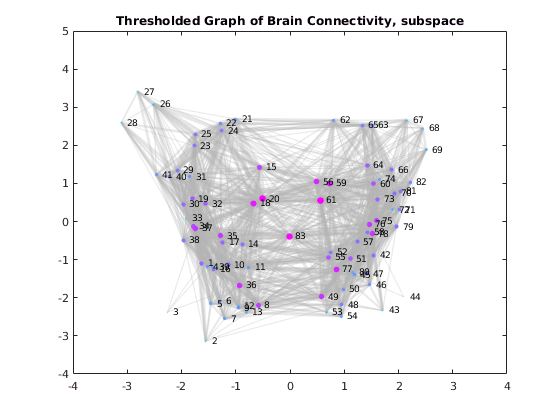

Jthresh = J;
Jthresh(J < 0.005*max(max(J))) = 0;
G = graph(Jthresh);
deg = degree(G);

edgeC = [0.7, 0.7, 0.7];

LWidths = G.Edges.Weight/max(G.Edges.Weight);
LWidths = log(LWidths)-min(log(LWidths)) + eps; % normalized

colormap cool                                       % set color map
H = plot(G, 'Layout', 'subspace', 'MarkerSize',5*(deg + 1)./max(deg), ...               % node size in log scale
    'NodeCData',deg,...                             % node color by degree
    'EdgeColor',edgeC,'EdgeAlpha',0.3,'LineWidth',LWidths);

title('Thresholded Graph of Brain Connectivity, subspace')

Now it looks like we're actually losing structure...Ok leaving the threshold at 0.005*max(J) is best. Very cool that the literale structure of the brain comes out of the connectivity matrix so easily. Brain stem in the middle, precuneus L and R (20 and 61) connecting the hemispheres, and nodes 1-41 in a distinct cluster from nodes 42-82.